# Load data

clear;clc;close all
frauds = readtable('D:\OneDrive - City, University of London\cityU\1-Machine Learning\CourseWork\data\CreditCardFraudDetection/creditcard.csv');
colNames = categorical(frauds(:,1:30).Properties.VariableNames);
colNames = reordercats(colNames);

## Data processing & Primary statistics

• check missing value and describtive statistics

summary(frauds)

Variables:

    Time: 284807×1 double

        Values:

            Min                0
            Median         84692
            Max       1.7279e+05

    V1: 284807×1 double

        Values:

            Min        -56.408
            Median    0.018109
            Max         2.4549

    V2: 284807×1 double

        Values:

            Min        -72.716
            Median    0.065486
            Max         22.058

    V3: 284807×1 double

        Values:

            Min       -48.326 
            Median    0.17985 
            Max        9.3826 

    V4: 284807×1 double

        Values:

            Min         -5.6832
            Median    -0.019847
            Max          16.875

    V5: 284807×1 double

        Values:

            Min         -113.74
            Median    -0.054336
            Max          34.802

    V6: 284807×1 double

        Values

missingvalues = sum(ismissing(frauds));

summaryTable = varfun(@(x) [mean(x);std(x);skewness(x);min(x);max(x)],frauds);
summaryTable.Properties.RowNames = {'mean' 'std' 'skewness' 'min' 'max'};
summaryTable.Properties.VariableNames = extractAfter(summaryTable.Properties.VariableNames,'Fun_');
disp(missingvalues);

  Columns 1 through 20

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 21 through 31

     0     0     0     0     0     0     0     0     0     0     0



disp(summaryTable);

                   Time           V1            V2             V3             V4            V5            V6            V7             V8            V9            V10           V11          V12           V13            V14            V15            V16            V17           V18           V19           V20            V21            V22            V23           V24            V25            V26           V27            V28        Amount      Class  
                <s

## • View hisgrams

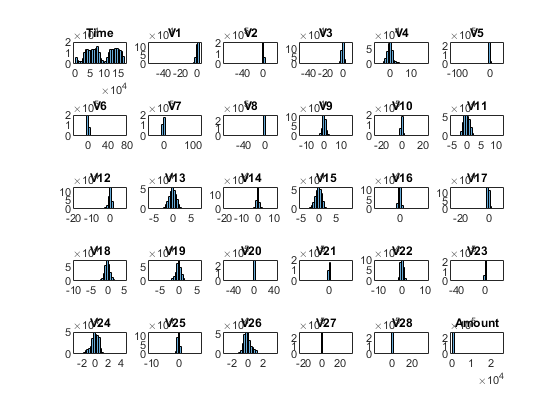

varnames = strrep(frauds.Properties.VariableNames,'_','');
figure(1)
for i = 1:30
    subplot(5,6,i)
    histogram(frauds{:,i},30)
    title(varnames(i));
end

## • View correlation matrix

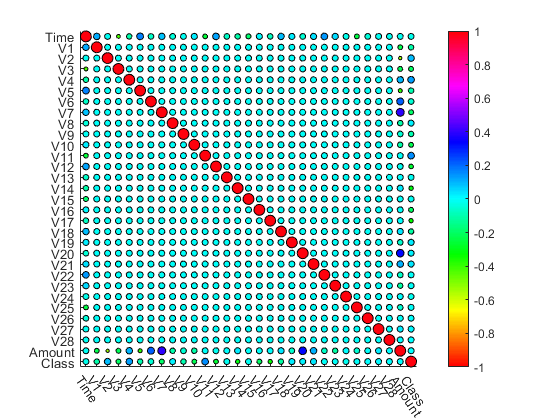

%%%%% if this part doesnt work pealse run second part

% %%%%% First part
% % view correlation matrix
% % Produce the input matrix data 
% varnames = strrep(frauds.Properties.VariableNames,'_','');
% fraud = table2array(frauds);
% C = corrcoef(fraud);
% % Set [min,max] value of C to scale colors
% clrLim = [-1,1];  % range
% % Set the  [min,max] of diameter where 1 consumes entire grid square
% diamLim = [0.1, 1];
% 
% % Compute center of each circle 
% % This assumes the x and y values were not entered in imagesc()
% x = 1 : 1 : size(C,2); % x edges
% y = 1 : 1 : size(C,1); % y edges
% [xAll, yAll] = meshgrid(x,y); 
% % Set color of each rectangle
% % Set color scale
% cmap = hsv(256); 
% Cscaled = (C - clrLim(1))/range(clrLim); % always [0:1]
% colIdx = discretize(Cscaled,linspace(0,1,size(cmap,1)));
% % Set size of each circle
% % Scale the size in the same way we scale the color
% diamSize = Cscaled * range(diamLim) + diamLim(1); 
% % Create figure
% fh = figure(); 
% ax = axes(fh); 
% hold(ax,'on')
% colormap(ax,'hsv');
% % Create circles
% theta = linspace(0,2*pi,50); % the smaller, the less memory req'd.
% h = arrayfun(@(i)fill(diamSize(i)/2 * cos(theta) + xAll(i), ...
%     diamSize(i)/2 * sin(theta) + yAll(i), cmap(colIdx(i),:)),1:numel(xAll)); 
% axis(ax,'equal')
% axis(ax,'tight')
% set(gca, 'XTick', 1:31); % x-axis bins
% set(gca, 'YTick', 1:31); % y-axis bins
% xticklabels(varnames);
% xtickangle(305);
% yticklabels(varnames);
% set(ax,'YDir','Reverse')
% colorbar()
% caxis(clrLim);


% The heatmap clearly shows which all variable are multicollinear in nature,
% and which variable have high collinearity with the target variable.

%%%%% Second part
figure(5)
set(gcf,'color','w');
fraud = table2array(frauds);
corr_matrix = corrcoef(fraud);
imagesc(corr_matrix); 
set(gca, 'XTick', 1:31); % x-axis bins
set(gca, 'YTick', 1:31); % y-axis bins
xticklabels(varnames);
xtickangle(305);
yticklabels(varnames);
set(gca, 'YTickLabel');

  0×0 empty cell array



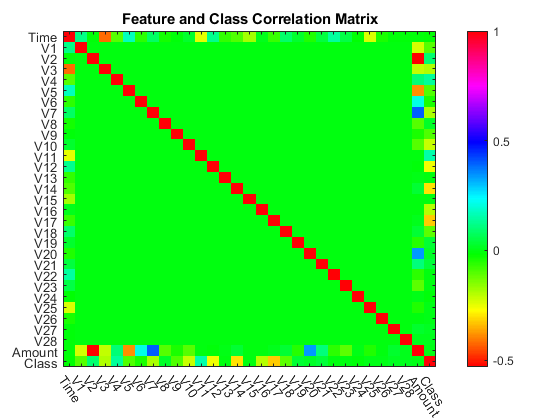

title('Feature and Class Correlation Matrix');
colormap('hsv'); 
colorbar;
hold off

## • Data partition

dataMatrix = frauds{:,1:30}; % convert traing data to matrix
TagMatrix = table2array(frauds(:,end)); % convert traing data labes to matrix

[m,n] = size(frauds) ;
P = 0.7; %dividing original data into training and testing dataset(0.7:0.3)
idx = randperm(m);
Training = frauds(idx(1:round(P*m)),:); 
Testing = frauds(idx(round(P*m)+1:end),:);

trainDataMatrix = dataMatrix(idx(1:round(P*m)),:);
trainTagMatrix = TagMatrix(idx(1:round(P*m)),:);

testDataMatrix = dataMatrix(idx(round(P*m)+1:end),:);
testTagMatrix = TagMatrix(idx(round(P*m)+1:end),:);

## Model 1: Random Forest

• Bayesian hyperparameter optimization

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        minLS |       numPTS |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |  0.00057598 |      509.46 |  0.00057598 |  0.00057598 |           11 |           30 |


|    2 | Best   |  0.00051865 |      339.48 |  0.00051865 |  0.00051904 |            6 |           18 |


|    3 | Accept |  0.00063151 |      78.565 |  0.00051865 |  0.00057535 |            5 |            2 |


|    4 | Accept |  0.00060527 |      173.37 |  0.00051865 |  0.00051869 |           17 |            7 |


|    5 | Accept |  0.00055536 |      352.26 |  0.00051865 |  0.00051871 |           20 |           21 |


|    6 | Accept |   0.0005209 |       258.1 |  0.00051865 |  0.00051874 |            1 |           16 |


|    7 | Accept |   0.0005193 |      305.61 |  0.00051865 |  0.00051879 |            1 |           19 |


|    8 | Accept |  0.00052737 |      293.16 |  0.00051865 |  0.00052095 |            1 |           18 |


|    9 | Best   |  0.00050781 |      272.96 |  0.00050781 |  0.00051703 |            1 |           17 |


|   10 | Best   |  0.00049437 |      266.15 |  0.00049437 |  0.00051211 |            1 |           17 |


|   11 | Accept |  0.00060011 |      240.97 |  0.00049437 |   0.0005128 |           20 |           16 |


|   12 | Accept |  0.00052216 |      451.77 |  0.00049437 |  0.00051346 |            1 |           26 |


|   13 | Accept |  0.00051724 |      436.95 |  0.00049437 |  0.00051352 |            1 |           21 |


|   14 | Accept |  0.00086555 |      76.202 |  0.00049437 |  0.00051317 |           20 |            1 |


|   15 | Accept |  0.00054097 |      118.59 |  0.00049437 |  0.00051241 |            6 |            4 |


|   16 | Accept |   0.0005025 |      203.66 |  0.00049437 |  0.00051305 |            1 |            8 |


|   17 | Accept |  0.00052381 |      251.52 |  0.00049437 |  0.00049901 |            6 |           10 |


|   18 | Accept |  0.00051338 |      182.97 |  0.00049437 |   0.0005035 |            1 |            6 |


|   19 | Accept |  0.00056334 |      439.66 |  0.00049437 |  0.00051212 |            9 |           24 |


|   20 | Accept |  0.00054844 |      534.38 |  0.00049437 |  0.00051219 |            1 |           30 |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        minLS |       numPTS |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   21 | Accept |  0.00051514 |      247.45 |  0.00049437 |  0.00050818 |            1 |            8 |


|   22 | Accept |  0.00056494 |      170.76 |  0.00049437 |  0.00051282 |            4 |            7 |


|   23 | Accept |  0.00054764 |      289.43 |  0.00049437 |  0.00051283 |            7 |           13 |


|   24 | Accept |  0.00051965 |      304.84 |  0.00049437 |  0.00051289 |            2 |           13 |


|   25 | Accept |  0.00054939 |      506.74 |  0.00049437 |  0.00051289 |            4 |           25 |


|   26 | Accept |  0.00058757 |      631.93 |  0.00049437 |  0.00051289 |           18 |           30 |


|   27 | Accept |  0.00078745 |      81.263 |  0.00049437 |  0.00051009 |           10 |            1 |


|   28 | Accept |  0.00052136 |      252.18 |  0.00049437 |  0.00051096 |            1 |           10 |


|   29 | Accept |  0.00052406 |      175.15 |  0.00049437 |  0.00051141 |            1 |            5 |


|   30 | Accept |  0.00049783 |       281.2 |  0.00049437 |    0.000508 |            1 |           11 |


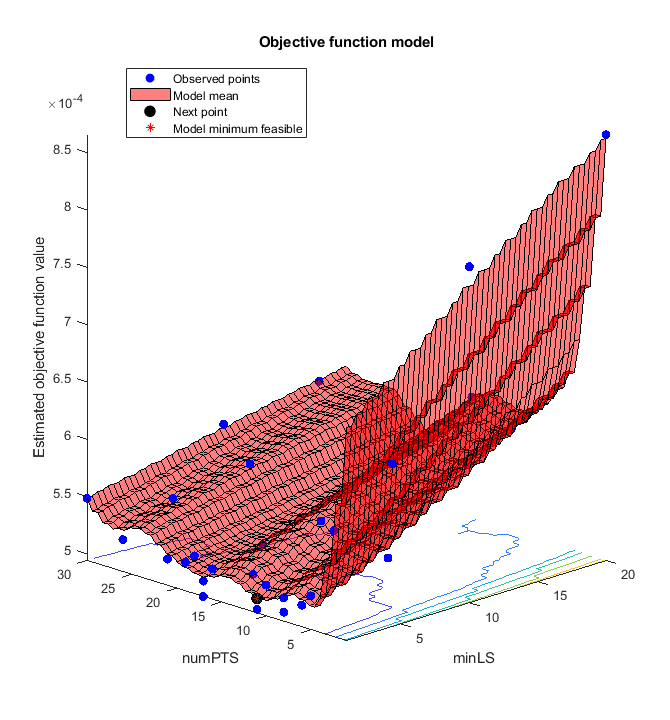

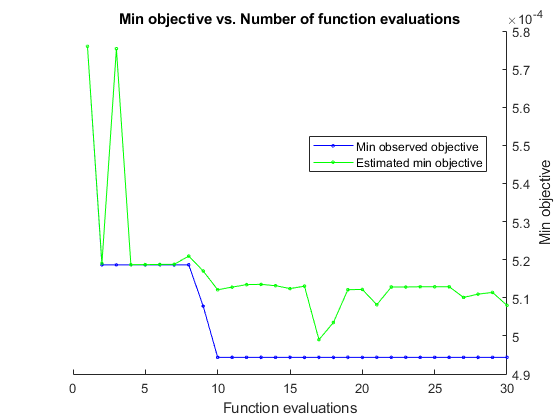


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 8784.0278 seconds
Total objective function evaluation time: 8726.7301

Best observed feasible point:
    minLS    numPTS
    _____    ______

      1        17  

Observed objective function value = 0.00049437
Estimated objective function value = 0.00051134
Function evaluation time = 266.1498

Best estimated feasible point (according to models):
    minLS    numPTS
    _____    ______

      1        10  

Estimated objective function value = 0.000508
Estimated function evaluation time = 259.802



t1=datetime('now');
rng('default'); % For reproducibility
minLS = optimizableVariable('minLS',[1,20],'Type','integer');
numPTS = optimizableVariable('numPTS',[1,30],'Type','integer');
hyperparametersRF = [minLS; numPTS];

results = bayesopt(@(params)oobErrRF(params,trainDataMatrix,trainTagMatrix),hyperparametersRF,...
    'AcquisitionFunctionName','expected-improvement-plus','Verbose',1);

t2=datetime('now');
totalTime=t2-t1;

## • Training RF Model

bestHyperparameters = results.XAtMinObjective;
Mdl = TreeBagger(100,trainDataMatrix,trainTagMatrix,'OOBPredictorImportance','on','Method','classification',...
    'MinLeafSize',bestHyperparameters.minLS,...
    'NumPredictorstoSample',bestHyperparameters.numPTS);

## • Plot feature importance

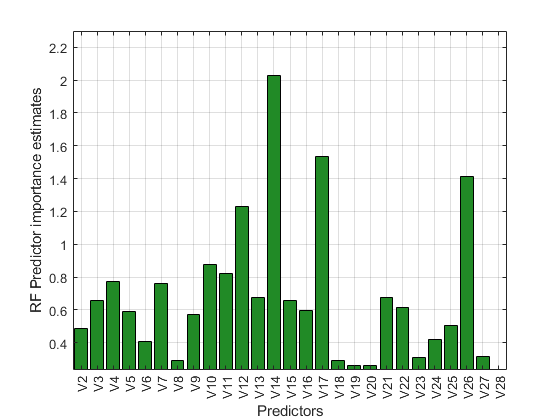

figure(88)
color = [0.13 0.54 0.15]; %color
imp = Mdl.OOBPermutedPredictorDeltaError;
c = bar(colNames,imp,'FaceColor',color);
b.FaceColor = 'flat';
ylabel('RF Predictor importance estimates');
xlabel('Predictors');
grid on

## • Classification error as a funtion of number of trees

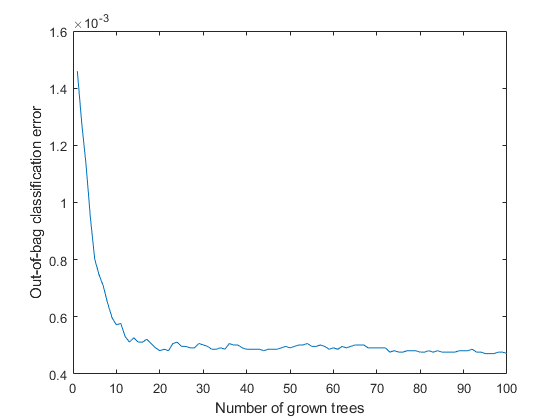

figure(5)
oobErrorBaggedEnsemble = oobError(Mdl);
plot(oobErrorBaggedEnsemble);
xlabel 'Number of grown trees';
ylabel 'Out-of-bag classification error';

## • Confusion matrix

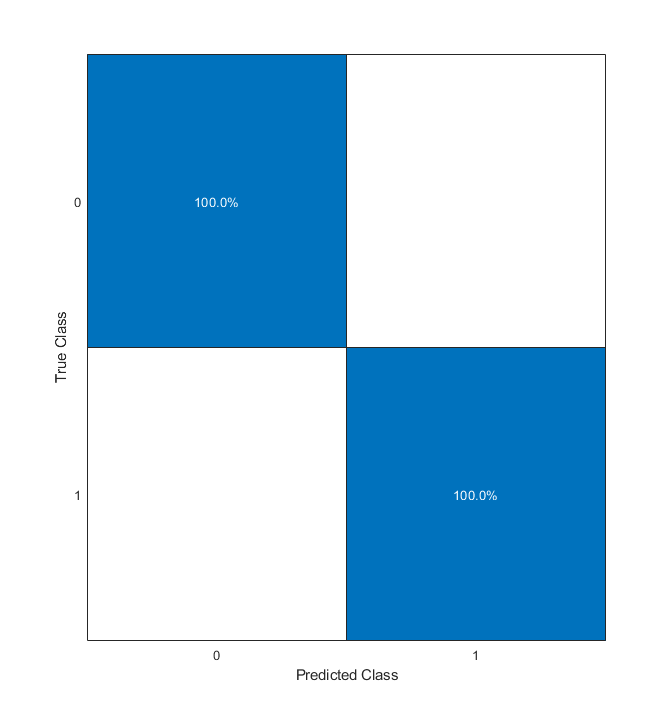

RFpredictedY_train = predict(Mdl, trainDataMatrix);
RFpredictedY_train = str2double(RFpredictedY_train);
figure(6)
cm = confusionchart(trainTagMatrix,RFpredictedY_train);
cm.Normalization = 'row-normalized';

## Model 2 Logistic Regression

• Lasso for generalized linear model

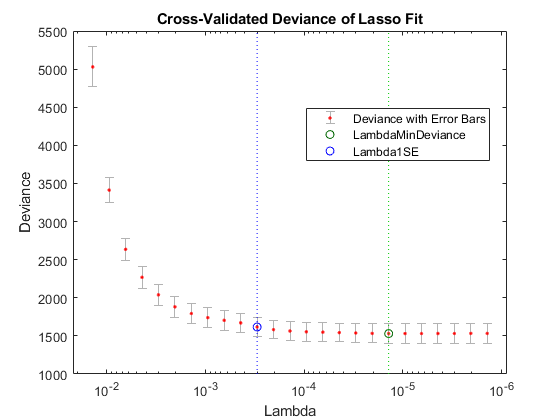

%Construct a regularized binomial regression using 25 Lambda values and 10-fold cross validation.
rng('default') % for reproducibility
[B,FitInfo] = lassoglm(trainDataMatrix,trainTagMatrix,'binomial',...
    'NumLambda',25,'CV',10);
lassoPlot(B,FitInfo,'PlotType','CV');    
legend('show','Location','best')

% The plot identifies the minimum-deviance point with a green circle and dashed line as a function of the
% regularization parameter Lambda. The blue circled point has minimum deviance plus no more than one standard deviation.

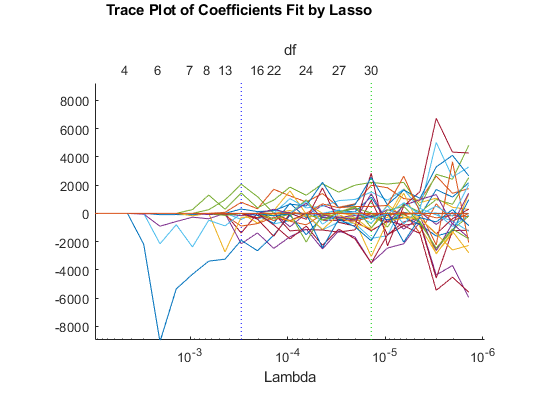

lassoPlot(B,FitInfo,'PlotType','Lambda','XScale','log');

% shhow nonzero model coefficients as a function of the regularization parameter Lambda.

indx = FitInfo.Index1SE;
B0 = B(:,indx);
nonzeros = sum(B0 ~= 0);
% Find the number of nonzero model coefficients at the Lambda value with minimum deviance plus one standard deviation poin

cnst = FitInfo.Intercept(indx);
B1 = [cnst;B0];

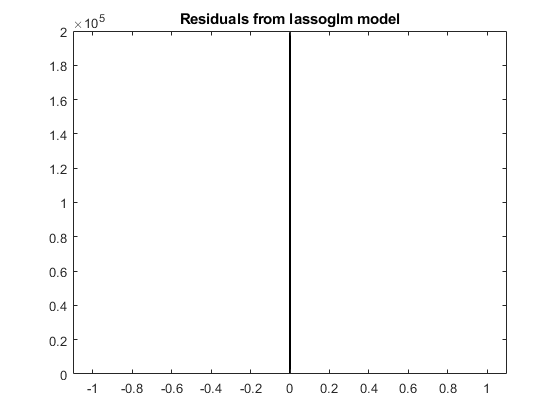

figure(8)
preds = glmval(B1,trainDataMatrix,'logit');
histogram(trainTagMatrix - preds) 
title('Residuals from lassoglm model')

% plot residuals from lassoglm model

predictors = find(B0); 
% indices of nonzero predictors

## • Train model

LRmd = fitglm(trainDataMatrix,trainTagMatrix,'linear',...
    'Distribution','binomial','PredictorVars',predictors);

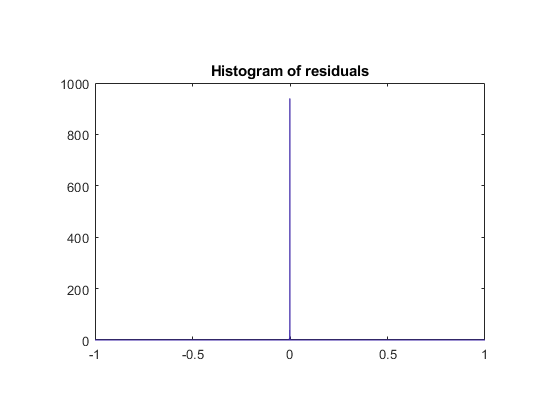

figure(9)
plotResiduals(LRmd)

% plot residuals

LRpredictedY_train_temp = predict(LRmd,trainDataMatrix);
LRpredictedY_train = (LRpredictedY_train_temp>=0.5);
LRpredictedY_train = double(LRpredictedY_train);

## • Confusion matrix

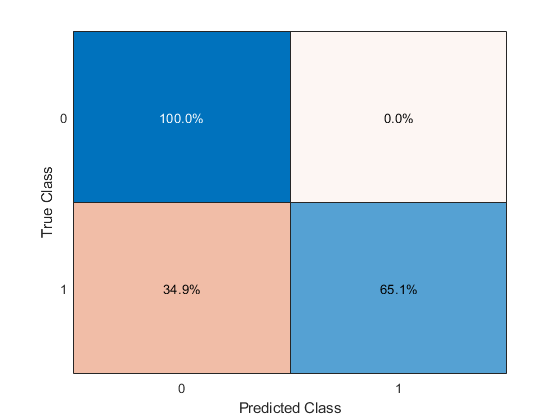

figure(10)
cm2 = confusionchart(trainTagMatrix,LRpredictedY_train);
cm2.Normalization = 'row-normalized';

## • Feature importance

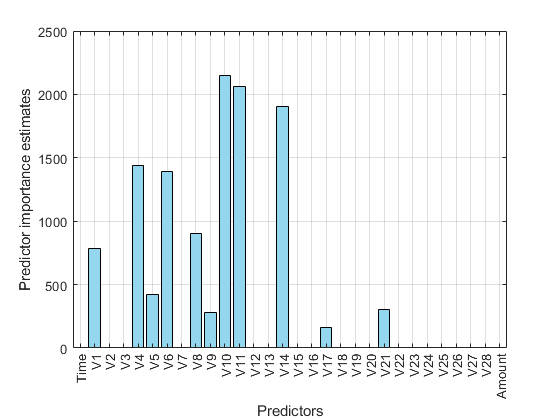

figure(7)
color2 = [0.58 0.84 0.93]; %color
b = bar(colNames,abs(B0),'FaceColor',color2);
b.FaceColor = 'flat';
ylabel('Predictor importance estimates');
xlabel('Predictors');
grid on

## Testing and Comparesion

### • RF Confusion matrix

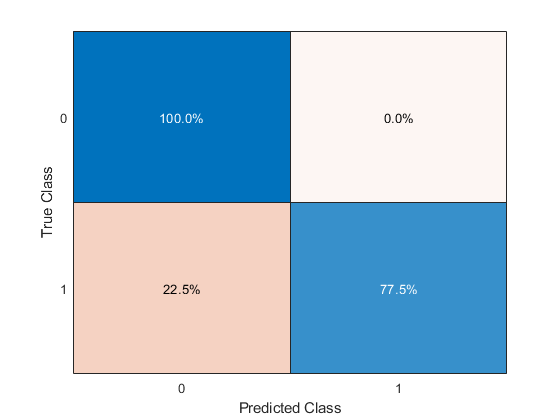

RFpredictedY_test = predict(Mdl,testDataMatrix);
RFpredictedY_test = str2double(RFpredictedY_test);
figure(11)
cm3 = confusionchart(testTagMatrix,RFpredictedY_test);
cm3.Normalization = 'row-normalized';


RFcon = confusionmat(testTagMatrix,RFpredictedY_test);
rfAcc = (RFcon(1,1)+RFcon(2,2))/sum(sum(RFcon));
rfRec = RFcon(2,2)/(RFcon(2,1)+RFcon(2,2));   
rfPre = RFcon(2,2)/(RFcon(1,2)+RFcon(2,2));      
randf  = 2/(1/rfPre + 1/rfRec);
fprintf('Random Forest Accuracy = %d',randf);

Random Forest Accuracy = 8.571429e-01

### • LR Confusion matrix

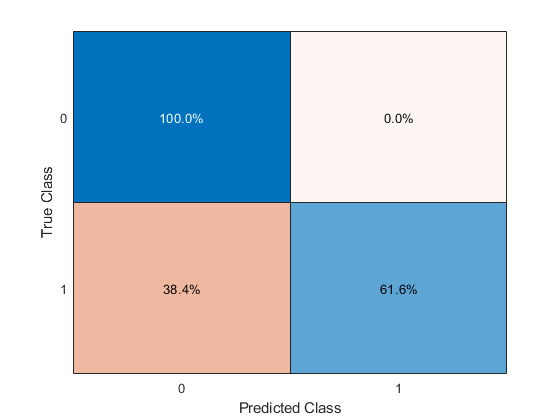

LRpredictedY_test_temp = predict(LRmd,testDataMatrix);
LRpredictedY_test = (LRpredictedY_test_temp>=0.5);
LRpredictedY_test = double(LRpredictedY_test);
figure(12)
cm4 = confusionchart(testTagMatrix,LRpredictedY_test);
cm4.Normalization = 'row-normalized';


LRcon = confusionmat(testTagMatrix,LRpredictedY_test);
logAcc = (LRcon(1,1)+LRcon(2,2))/sum(sum(LRcon));
logRec = LRcon(2,2)/(LRcon(2,1)+LRcon(2,2));   
logPre = LRcon(2,2)/(LRcon(1,2)+LRcon(2,2));      
logit  = 2/(1/logPre + 1/logRec);
fprintf('logistic Regression Accuracy = %d',logit);

logistic Regression Accuracy = 7.181467e-01

### • ROC Curves and AUC

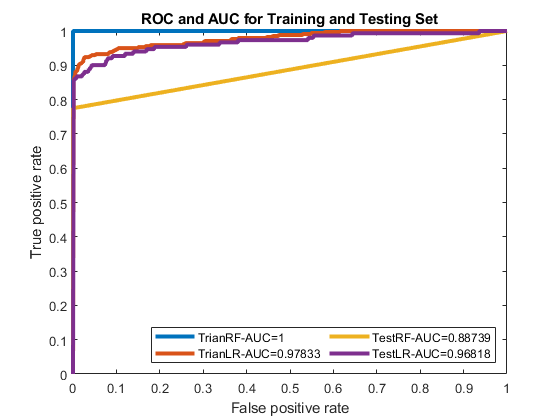

curves = zeros(4,1); labels = cell(4,1);
[RFtrainX,RFtrainY,RFtrainT,RFtrainAUC] = perfcurve(trainTagMatrix,RFpredictedY_train,1);
[LRtrainX,LRtrainY,LRtrainT,LRtrainAUC] = perfcurve(trainTagMatrix,LRpredictedY_train_temp,1);
[RFtestX,RFtestY,RFtestT,RFtestAUC] = perfcurve(testTagMatrix,RFpredictedY_test,1);
[LRtestX,LRtestY,LRtestT,LRtestAUC] = perfcurve(testTagMatrix,LRpredictedY_test_temp,1);

figure(13)
plot(RFtrainX,RFtrainY,'LineWidth',3,'DisplayName',strcat('TrianRF-AUC=',num2str(RFtrainAUC)))
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC and AUC for Training and Testing Set')

hold on
plot(LRtrainX,LRtrainY,'LineWidth',3,'DisplayName',strcat('TrianLR-AUC=',num2str(LRtrainAUC)))
plot(RFtestX,RFtestY,'LineWidth',3,'DisplayName',strcat('TestRF-AUC=',num2str(RFtestAUC)))
plot(LRtestX,LRtestY,'LineWidth',3,'DisplayName',strcat('TestLR-AUC=',num2str(LRtestAUC)))
hold off
lgd = legend('Location','southeast');
lgd.NumColumns = 2;

modelNames = {'LogisticRegression','RandomForest'};
perfMeasures = {'Accuracy', 'Recall', 'Precision', 'f1 score', 'AUC'};
res = [logAcc,rfAcc;logRec,rfRec;logPre,rfPre;logit,randf;...
    LRtestAUC(1)*100,RFtestAUC(1)*100];
restable= array2table(res,'RowNames',perfMeasures,'VariableNames',modelNames);
disp(restable);

                 LogisticRegression    RandomForest
                 __________________    ____________

    Accuracy          0.99915            0.99954   
    Recall            0.61589            0.77483   
    Precision         0.86111            0.95902   
    f1 score          0.71815            0.85714   
    AUC                96.818             88.739   



## FunctionSummary

function oobErr = oobErrRF(params,trainDataMatrix,trainTagMatrix)
%oobErrRF Trains random forest and estimates out-of-bag ensemble error
%   oobErr trains a random forest of 100 regression trees using the
%   predictor data in X and the parameter specification in params, and then
%   returns the out-of-bag quantile error based on the median. X is a table
%   and params is an array of OptimizableVariable objects corresponding to
%   the minimum leaf size and number of predictors to sample at each node.
randomForest = TreeBagger(100,trainDataMatrix,trainTagMatrix,'Method','classification',...
    'OOBPrediction','on','MinLeafSize',params.minLS,...
    'NumPredictorstoSample',params.numPTS);
oobErr = mean(oobError(randomForest));
end